Show three example shapes, together with their absolute and relative attianable wrench hulls.

l = 0.5;

f_affine_curvature = @(s, a, b) [
    l*ones(size(s)); % TODO: This seems suspect - but for these tests it's really hard to consider what this should be
    zeros(size(s));
    a*s + b
];

N_nodes = 6;
s = linspace(0, 1, N_nodes);
cell_segment_twists = cell(1, 3);
cell_segment_twists{1} = f_affine_curvature(s, -2, 3);
cell_segment_twists{2} = f_affine_curvature(s, 2, 1);
cell_segment_twists{3} = f_affine_curvature(s, 8, -1);

Make the arm design

pose_base = [0; 0; -pi/2];
g_0 = Pose2.hat(pose_base);

rho_outer = 0.08;
rho_inner = 0.015;

rhos = [-rho_outer, -rho_inner, rho_inner, rho_outer];
mat_A = [
    1, 1, 1, 1;
    0, 0, 0, 0;
    -rhos;
    ];

f_bellow = @FittedBellowMechanics.actuator_force;
f_muscle = @FittedMuscleMechanics.actuatorForce_key;
fs = {f_bellow, f_muscle, f_muscle, f_bellow};

l_0 = 0.50;

p_bounds = [50; 100; 100; 50];

% Combine the design parameters into a struct
struct_design = struct();
struct_design.mat_A = mat_A;
struct_design.l_0 = l_0;
struct_design.fs = fs;
struct_design.g_0 = g_0;
struct_design.rhos = rhos;
struct_design.p_bounds = p_bounds;

color_light_gray = [175, 175, 175] / 255;
color_gray = [150 150 150] / 255;

color_green = [45 182 125] / 255;
color_yellow = [255 176 0] / 255;
color_blue = [100 143 255] / 255;
color_red = [255 48 150] / 255;
colors = [color_red; color_blue; color_green];

% Lighter colors
color_light_green = [130 205 174] / 255;
color_light_yellow = [248 203 97] / 255;
color_light_blue = [135 167 250] / 255;
color_light_red = [230 100 164] / 255;

% Darker colors
color_dark_green = [0.0706    0.5137    0.3294];
color_dark_blue = [0.2941    0.4196    0.7490];
color_dark_yellow = [0.7490    0.5176         0];
color_dark_red = [0.6549    0.1059    0.3725];
colors_dark = [color_dark_red; color_dark_blue; color_dark_green];

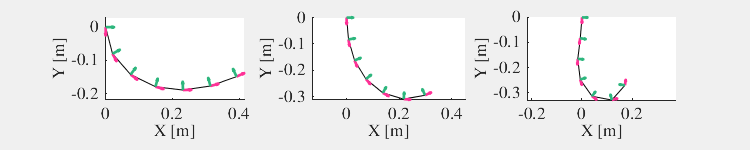

fig_arms = figure("Visible", true, "Position", [0, 0, 750, 150]);
t = tiledlayout(fig_arms, 1, 3, "Tilespacing", "compact");
%%% Frame 1: plot the target backbone shape
for i_shape = 1 : numel(cell_segment_twists)
    segment_twists_i = cell_segment_twists{i_shape};
    ax = nexttile(t, [1, 1]);
    poses_i = calc_poses(struct_design.g_0, segment_twists_i);
    plot_poses(poses_i, ax);
    xlabel("X [m]")
    ylabel("Y [m]")
end

fontname("nimbus roman")
fontsize(13, "points")

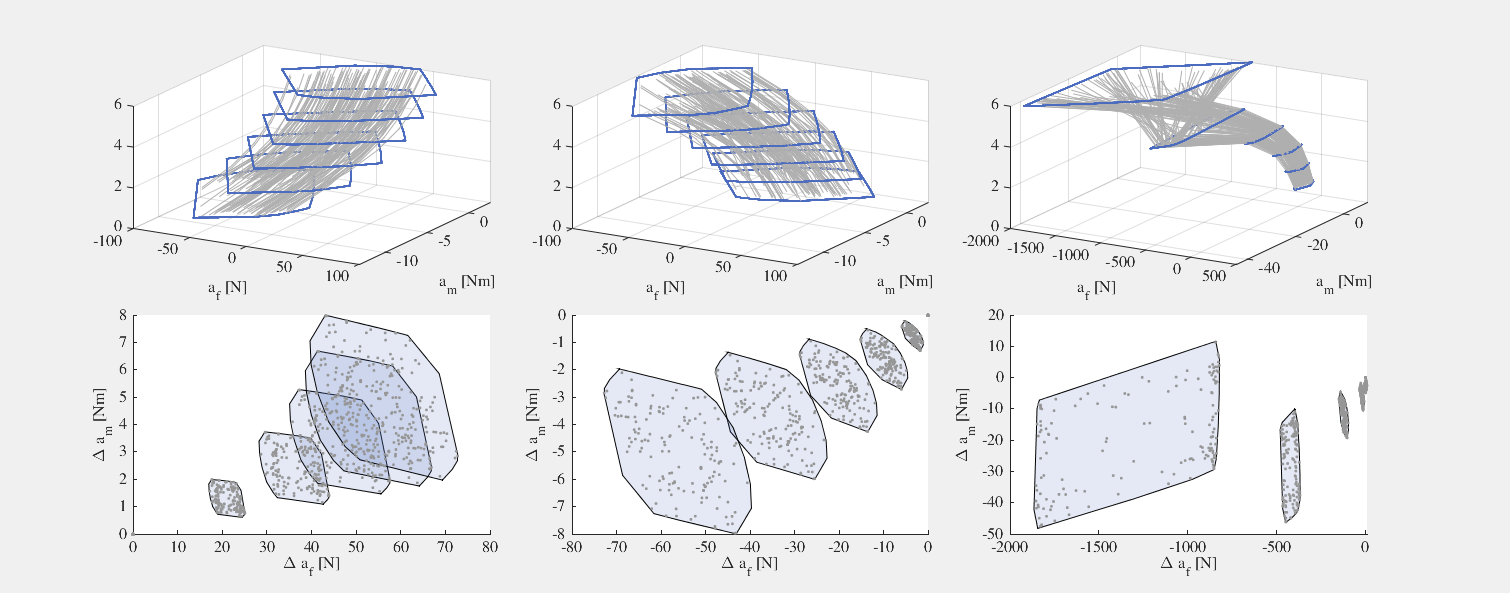

% Sample pressures
rng(100);
N_p_sample = 150;
p_interior = diag(struct_design.p_bounds) * betarnd(0.3, 0.3, 4, N_p_sample);

% Sample boundary pressures and compute their corresponding wrench space
% metrics
p_bndry = sample_edges_of_cuboid(4, struct_design.p_bounds);

fig = figure("Visible", true, "Position", [0, 0, 1500, 600]);
t = tiledlayout(fig, 2, 3, "Tilespacing", "compact", "TileIndexing", "columnmajor");
for i_shape = 1 : numel(cell_segment_twists)
    segment_twists_i = cell_segment_twists{i_shape};
   

    %%% Frame 2: plot the absolute wrench hull
    % Compute absolute and relative attainble wrench hulls
    ax = nexttile(t, [1, 1]);
    [interior_af, interior_am] = compute_reaction_traces(p_interior, segment_twists_i, struct_design);
    [bndry_af, bndry_am] = compute_reaction_traces(p_bndry, segment_twists_i, struct_design);
    i_bndry = boundary(bndry_af(1, :)', bndry_am(1, :)', 0);
    
    hold on
    plot3(interior_af', interior_am', 1:N_nodes,"color", color_light_gray, "markerfacecolor", color_light_gray, "markersize", 2, "linewidth", 0.5);
    plot_wrench_hull_loops(bndry_af, bndry_am, ax, struct("color", color_dark_blue, "linewidth", 1));
    %plot_wrench_hull_white_lie(bndry_af, bndry_am, ax, color_blue);
    
    view(30, 30)
    grid on
    xlabel("a_f [N]")
    ylabel("a_m [Nm]")

    %%% Frame 3: plot the relative wrench hull
    ax = nexttile(t, [1, 1]);
    interior_rltv_af = interior_af - interior_af(1, :);
    interior_rltv_am = interior_am - interior_am(1, :);

    rltv_bndry_af = bndry_af - bndry_af(1, :);
    rltv_bndry_am = bndry_am - bndry_am(1, :);

    
    hold on
    for i = 2 : N_nodes
        %fill(ax, cell_afs{i}, cell_ams{i}, color_dark_blue, "facealpha", 0.15);
        i_bndry = boundary(rltv_bndry_af(i, :)', rltv_bndry_am(i, :)', 0);
        fill(ax, rltv_bndry_af(i, i_bndry), rltv_bndry_am(i, i_bndry), color_dark_blue, "facealpha", 0.15);
    end
    plot(interior_rltv_af, interior_rltv_am, ".", "color", color_gray);
    xlabel("\Delta a_f [N]")
    ylabel("\Delta a_m [Nm]")
end
fontname("Nimbus Roman")
fontsize(15, "points")


function [cell_rltv_bndry_af_per_node, cell_rltv_bndry_am_per_node] = relative_attainable_wrench_hull(bndry_af, bndry_am)
    N_nodes = size(bndry_af, 1);

    cell_rltv_bndry_af_per_node = cell(1, N_nodes);
    cell_rltv_bndry_am_per_node = cell(1, N_nodes);

    cell_rltv_bndry_af_per_node{1} = [0, 0];
    cell_rltv_bndry_am_per_node{1} = [0, 0];

    % Compute all the relative attainble reaction traces
    % These points will form the boundary of the relatively attainable
    % reaction space for each node. 
    rltv_bndry_af = bndry_af - bndry_af(1, :);
    rltv_bndry_am = bndry_am - bndry_am(1, :);

    for i = 2 : N_nodes
        % Order the points for each node, and only keep the ones that
        % contribute to the convex hull
        i_bndry = boundary(rltv_bndry_af(i, :)', rltv_bndry_am(i, :)', 0);

        cell_rltv_bndry_af_per_node{i} = rltv_bndry_af(i, i_bndry);
        cell_rltv_bndry_am_per_node{i} = rltv_bndry_am(i, i_bndry);
    end
end